clear; close all;


Drives = string(char('A':'Z')');
for i = 1:length(Drives)
    if isfolder(Drives(i)+":\OneDrive")
        DataFolder  = Drives(i) + ":\OneDrive\YuLab\Work\GPS\Data\";
        break;
    end
end
[ProgressClassFile, ProgressClassFolder, tf] = uigetfile(DataFolder+"\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


FPs = obj.TargetFP;
beh = obj.BehavTable;

SessionPre = find(obj.Label=="PreLesion");
SessionLesion = find(obj.Label=="Lesion");
NumPre = length(SessionPre);
NumLesion = length(SessionLesion);
SessionLabel = [-length(SessionPre):1:-1 1:length(SessionLesion)];

HD = obj.HDSorted; HDPDF = obj.HDPDF; HDCDF = obj.HDCDF;
RT = obj.RTSorted; RTPDF = obj.RTPDF; RTCDF = obj.RTCDF;
MT = obj.MTSorted; MTPDF = obj.MTPDF; MTCDF = obj.MTCDF;

C = GPSColor();

## Hold duration and reaction time

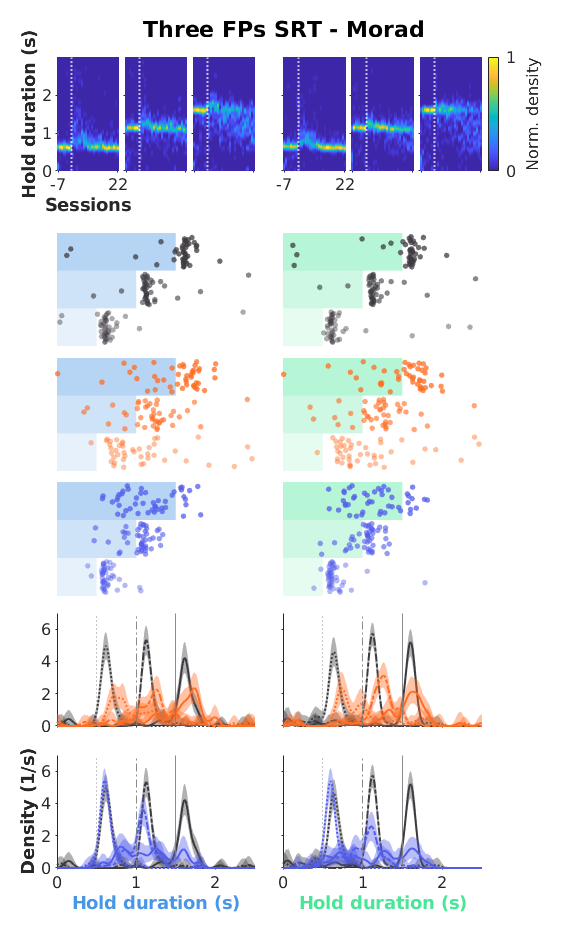

fig_hd = figure(31); clf(fig_hd);
set(fig_hd, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 10 16.5], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_hd, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

drawHeatmap(fig_hd, [1 13.5 7.5 2.5], [3.5 2], HDPDF, NumPre, NumLesion)

% show trials
DrawTrials(fig_hd, [1 6 7.5 6.4], [3.5 2], HD);

% plot PDFs and CDFs
DrawDistr(fig_hd, [1 1.2 7.5 4.5], [3.5 2], HDPDF);

fig_name = sprintf("Test_%s_HD_SRT_Lesion_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_hd, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_hd, fig_path+".pdf", 'ContentType', 'vector');

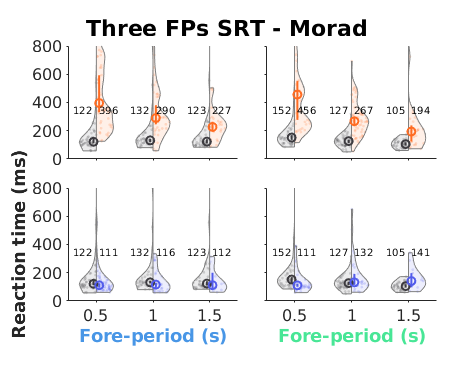

fig_response = figure(32); clf(fig_response);
set(fig_response, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 6.5], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_response, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_rt = DrawViolin(fig_response, [1.2 1.2 6.5 4.5], [3 2], obj, RT, 1000);
for i=1:numel(ax_rt)
    ax_rt{i}.YLim=[0 800];
end
ylabel(ax_rt{2,1}, "Reaction time (ms)", 'FontWeight', 'bold');

fig_name = sprintf("Test_%s_Reaction_SRT_Lesion_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_response, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_response, fig_path+".pdf", 'ContentType', 'vector');

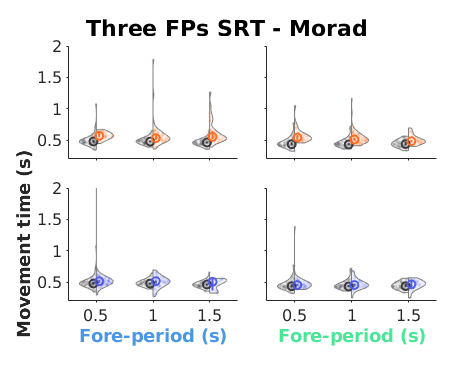

fig_movement = figure(33); clf(fig_movement);
set(fig_movement, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 6.5], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_movement, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_mt = DrawViolin(fig_movement, [1.2 1.2 6.5 4.5], [3 2], obj, MT, 1);
for i=1:numel(ax_mt)
    ax_mt{i}.YLim=[0.2 2];
end
ylabel(ax_mt{2,1}, "Movement time (s)", 'FontWeight', 'bold');

fig_name = sprintf("Test_%s_Movement_SRT_Leison_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_movement, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_movement, fig_path+".pdf", 'ContentType', 'vector');

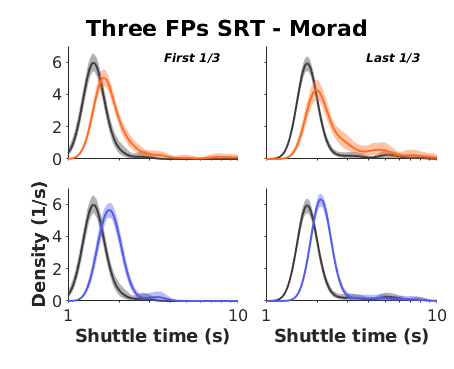

fig_st = figure(34); clf(fig_st);
set(fig_st, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 6.5], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_st, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

DrawShuttle(fig_st, [1.2 1.2 6.5 4.5], [3 2], obj.LogSTPDF);

fig_name = sprintf("Test_%s_ST_SRT_Lesion_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_st, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_st, fig_path+".pdf", 'ContentType', 'vector');

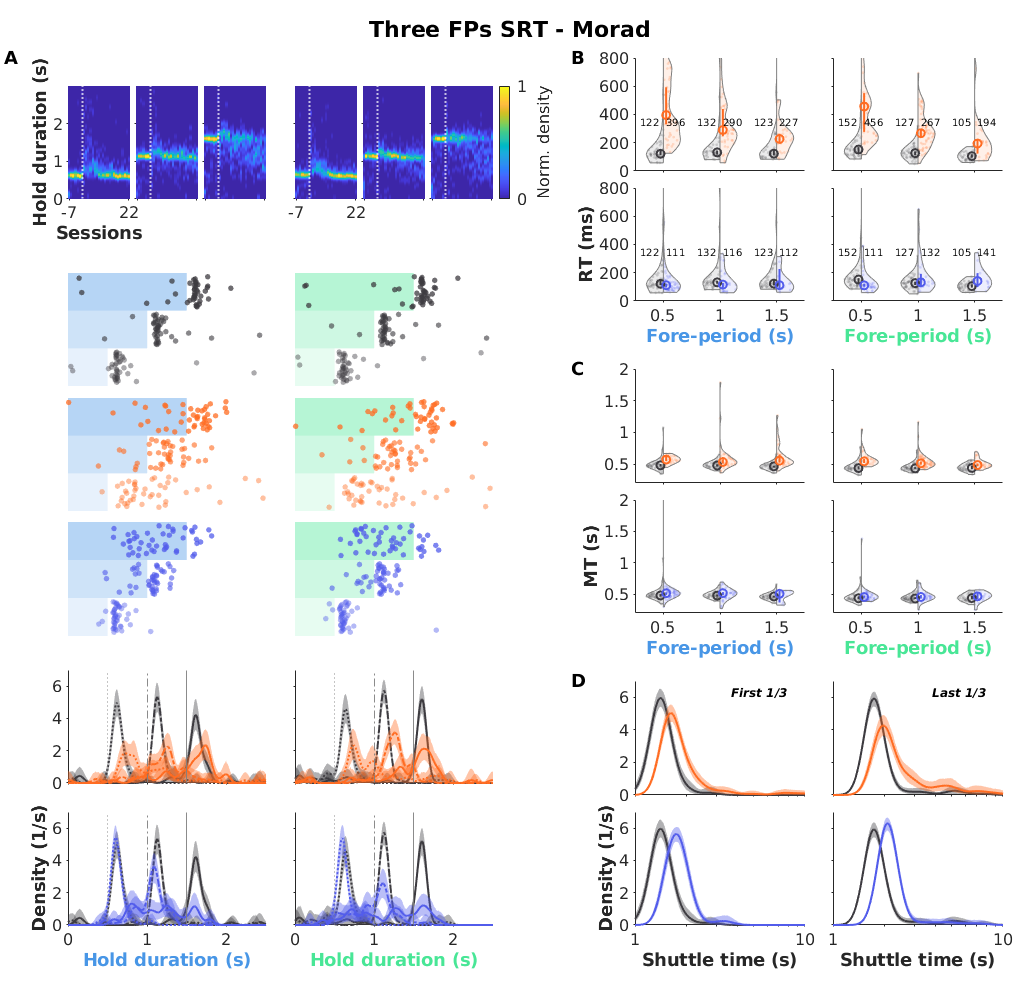

fig_total = figure(30); clf(fig_total);
set(fig_total, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 18 17.5], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_total, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

% Hold duration
% heatmap
drawHeatmap(fig_total, [1.2 14 7.5 2.5], [3.5 2], HDPDF, NumPre, NumLesion)
add_serial(fig_total, [1.2 14 7.5 2.5], 'A', [-1 0])

% show trials
DrawTrials(fig_total, [1.2 6.3 7.5 6.4], [3.5 2], HD);

% plot PDFs and CDFs
DrawDistr(fig_total, [1.2 1.2 7.5 4.5], [3.5 2], HDPDF);

% Reaction time
ax_rt = DrawViolin(fig_total, [11.2 12.2 6.5 4.3], [3 2], obj, RT, 1000);
for i=1:numel(ax_rt)
    ax_rt{i}.YLim=[0 800];
end
ylabel(ax_rt{2,1}, "RT (ms)", 'FontWeight', 'bold');
add_serial(fig_total, [11.2 12.2 6.5 4.3], 'B', [-1 0])

% Movement time
ax_mt = DrawViolin(fig_total, [11.2 6.7 6.5 4.3], [3 2], obj, MT, 1);
for i=1:numel(ax_mt)
    ax_mt{i}.YLim=[0.2 2];
end
ylabel(ax_mt{2,1}, "MT (s)", 'FontWeight', 'bold');
add_serial(fig_total, [11.2 6.7 6.5 4.3], 'C', [-1 0])

% Shuttle time
DrawShuttle(fig_total, [11.2 1.2 6.5 4.3], [3 2], obj.LogSTPDF);
add_serial(fig_total, [11.2 1.2 6.5 4.3], 'D', [-1 0])

fig_name = sprintf("Test_%s_SRT_Lesion_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_total, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_total, fig_path+".pdf", 'ContentType', 'vector');

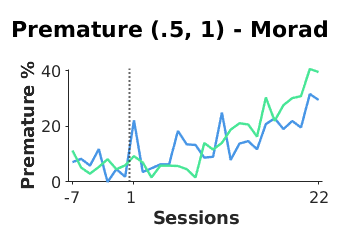

fig_premature = figure(40); clf(fig_premature);
set(fig_premature, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 6 4.2], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_premature, sprintf("Premature (.5, 1) - %s", obj.Subject), 'FontSize', 11);
ax_pre = axes(fig_premature, "Units", "centimeters", "Position", [1.2 1 4.5 2], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');

pre_rate_l = zeros(2, obj.NumSessions);
pre_rate_r = zeros(2, obj.NumSessions);

for i = 1:obj.NumSessions

    id_i_1     = beh.Session==obj.Sessions(i) & beh.Stage==1 & ismember(beh.FP, [1 1.5]);
    id_i_2     = beh.Session==obj.Sessions(i) & beh.Stage==1 & beh.FP==1.5;

    id_l_1     = id_i_1 & beh.PortCorrect==1;
    id_l_1_pre = beh.HD(id_l_1) > 0.5 & beh.HD(id_l_1) < 1;
    id_l_2     = id_i_2 & beh.PortCorrect==1;
    id_l_2_pre = beh.HD(id_l_2) > 1 & beh.HD(id_l_2) < 1.5;
    pre_rate_l(1, i) = sum(id_l_1_pre) / sum(id_l_1);
    pre_rate_l(2, i) = sum(id_l_2_pre) / sum(id_l_2);

    id_r_1     = id_i_1 & beh.PortCorrect==2;
    id_r_1_pre = beh.HD(id_r_1) > 0.5 & beh.HD(id_r_1) < 1;
    id_r_2     = id_i_2 & beh.PortCorrect==2;
    id_r_2_pre = beh.HD(id_r_2) > 1 & beh.HD(id_r_2) < 1.5;
    pre_rate_r(1, i) = sum(id_r_1_pre) / sum(id_r_1);
    pre_rate_r(2, i) = sum(id_r_2_pre) / sum(id_r_2);
end

plot(ax_pre, 1:obj.NumSessions, 100*pre_rate_l(1,:), 'Color', C.PortL, 'LineWidth', 1.2);
plot(ax_pre, 1:obj.NumSessions, 100*pre_rate_r(1,:), 'Color', C.PortR, 'LineWidth', 1.2);
set(ax_pre, 'XLim', [.5 obj.NumSessions+.5], ...
    'XTick', [1 NumPre+1 NumPre+NumLesion], 'XTickLabel', [-NumPre 1 NumLesion]);
xlabel(ax_pre, 'Sessions', 'FontWeight', 'bold');
ylabel(ax_pre, 'Premature %', 'FontWeight', 'bold');
xline(ax_pre, NumPre+.5, 'LineStyle', ':', 'LineWidth', 1)

fig_name = sprintf("Test_%s_Pre_SRT_Lesion_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_premature, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_premature, fig_path+".pdf", 'ContentType', 'vector');

StatTable = struct();
Vars = ["ST", "LogST", "HD", "RT", "MT"];
Labels = ["PreControl", "LesionEarly", "LesionExtensive"];

table_name = sprintf("Test_%s_SRT_Lesion_%s.xlsx", obj.Task, obj.Subject);
table_path = fullfile(FigFolder, table_name);

for i = 1:length(Vars)
    v_i = Vars(i);
    stat_1 = obj.(v_i+"Stat").(Labels(1));
    stat_1 = addvars(stat_1, repmat(Labels(1), height(stat_1), 1), 'NewVariableNames', "Label", 'Before', 1);
    StatTable.(v_i) = stat_1;
    for j = 2:length(Labels)
        lb_j = Labels(j);
        stat_j = obj.(v_i+"Stat").(lb_j);
        stat_j = addvars(stat_j, repmat(lb_j, height(stat_j), 1), 'NewVariableNames', "Label", 'Before', 1);
        StatTable.(v_i) = vertcat(StatTable.(v_i), stat_j);
    end

    writetable(StatTable.(v_i), table_path, 'Sheet', v_i);
end


function drawHeatmap(fig, pos, ax_sz, HDPDF, NumPre, NumLesion)
ax_w = (ax_sz(1)-(2*.1))/3;
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
dist_w = sep_w + ax_sz(1);
for p = 1:2
    x_now = pos(1) + dist_w * (p-1);
    y_now = pos(2);
    for fp = 1:3

        pd = cellfun(@(x) x{fp,p}.f, HDPDF.Session, 'UniformOutput', false);
        pd = cell2mat(pd);
        pd = pd';
        pd = pd./max(max(pd));

        ax = axes(fig, "Units", "centimeters", "Position", [x_now+1.2*(fp-1) y_now ax_w ax_sz(2)], ...
            'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out', 'YDir','normal');

        [num_bins, num_session] = size(pd);
        imagesc(ax, pd);
        xline(ax, NumPre+.5, 'Color', [1 1 1], 'LineWidth', 1, 'LineStyle', ':');
        set(ax, 'XLim', [.5 num_session+.5], 'YLim', [.5 num_bins+.5], ...
            'XTick', [1 NumPre+NumLesion], 'XTickLabel', [-NumPre NumLesion], 'XTickLabelRotation', 0, ...
            'YTick', 0.5:500:1251, 'YTickLabel', 0:1:2.5);
        if fp~=1
            set(ax, 'XTickLabel', [], 'YTickLabel', []);
        else
            if p==1
                ylabel(ax, "Hold duration (s)", 'FontWeight', 'bold');
                xlabel(ax, "Sessions", 'FontWeight', 'bold');
            else
                set(ax, 'YTickLabel', []);
            end
        end
    end
end
cb = colorbar(ax, 'units', 'centimeters', 'position', [x_now+1.2*3 y_now .2 2]);
cb.Limits = [0 cb.Limits(2)];
cb.Ticks = [0 1];
cb.Label.String = "Norm. density";
cb.FontSize = 8;
end

function ax = DrawTrials(fig, pos, ax_sz, data)
%% Show trials
Ports = ["L", "R"];
Labels = ["PreControl", "LesionEarly", "LesionExtensive"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 3*ax_sz(2) ) / 2;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

ax = cell(3,2);
for p = 1:2
    for l = 1:3
        x_now = pos(1) + dist_w * (p-1);
        y_now = pos(2) + dist_h * (3-l);

        ax{l,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
            'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
        plot_trials(ax{l,p}, data.(Labels(l))(:,1), 'FP', [.5 1 1.5], ...
            'FaceColor', GPSColor.("Port"+Ports(p)), 'MarkerColor', GPSColor.(Labels(l)), 'MarkerSize', 8);
        set(ax{l,p}, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');
    end
end

drawnow();
end % DrawTrials

%%
function ax = DrawDistr(fig, pos, ax_sz, data_pdf)
%% Plot pdf and cdf
Ports = ["L", "R"];
Labels = ["PreControl", "LesionEarly", "LesionExtensive"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 2*ax_sz(2) ) / 1;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

ax = cell(2,2);
ymax = max(max(cellfun(@(x1, x2, x3) max([x1.ci(2,:) x2.ci(2,:) x3.ci(2,:)]), data_pdf.PreControl, data_pdf.LesionEarly, data_pdf.LesionExtensive)));
ylim = ceil(ymax);

for p = 1:2
    for l = 1:2
        x_now = pos(1) + dist_w * (p-1);
        y_now = pos(2) + dist_h * (2-l);

        ax{l,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
            'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');

        distr_1 = data_pdf.(Labels(1))(:,p);
        distr_2 = data_pdf.(Labels(1+l))(:,p);

        plot_distr(ax{l,p}, distr_1, 'FP', [.5 1 1.5], ...
            'Color', GPSColor.(Labels(1)), 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
        plot_distr(ax{l,p}, distr_2, 'FP', [.5 1 1.5], ...
            'Color', GPSColor.(Labels(1+l)), 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);

        if p==1
            if l==2
                ylabel(ax{l,p}, "Density (1/s)", 'FontWeight', 'bold');
            end
        else
            set(ax{l,p}, 'YTickLabel', '');
        end
        if l==2
            xlabel(ax{l,p}, "Hold duration (s)", 'FontWeight', 'bold', 'Color', GPSColor.("Port"+Ports(p)));
        else
            set(ax{l,p}, 'XTickLabel', '');
        end
        set(ax{l,p}, 'XLim', [0 2.5], 'YLim', [0 ylim]);
    end
end

drawnow();
end % DrawDistr

%%
function ax = DrawViolin(fig, pos, ax_sz, obj, data, scale)
%% Plot violin comparations
Ports = ["L", "R"];
Labels = ["PreControl", "LesionEarly", "LesionExtensive"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 2*ax_sz(2) ) / 1;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

ax = cell(2,2);
for p = 1:2
    for l = 1:2
        x_now = pos(1) + dist_w * (p-1);
        y_now = pos(2) + dist_h * (2-l);

        ax{l,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
            'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');

        rt_1 = data.(Labels(1))(:,p);
        rt_2 = data.(Labels(1+l))(:,p);

        plot_violin_compare(ax{l,p}, rt_1, rt_2, obj.BandWidth, ...
            'cate_name', string(obj.TargetFP), 'Color', {GPSColor.(Labels(1)), GPSColor.(Labels(1+l))}, 'Scale', scale, 'Text', true);

        if p==2
            set(ax{l,p}, 'YTickLabel', '');
        end
        if l==2
            xlabel(ax{l,p}, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.("Port"+Ports(p)));
        else
            set(ax{l,p}, 'XTickLabel', '');
        end
        set(ax{l,p}, 'XLim', [.5 3.5]);
    end
end
end % DrawViolin

%%

function ax = DrawShuttle(fig, pos, ax_sz, data)
%% Plot shuttle time (first and last 1/3 trials)
Labels = ["PreControl", "LesionEarly", "LesionExtensive"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 2*ax_sz(2) ) / 1;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

st_pd_max = max(max(cellfun(@(x1, x2, x3) max([x1.ci(2,:) x2.ci(2,:) x3.ci(2,:)]), data.PreControl, data.LesionEarly, data.LesionExtensive)));
st_pd_ylim = ceil(st_pd_max);

ax = cell(2,2);
for p = 1:2
    for l = 1:2
        x_now = pos(1) + dist_w * (p-1);
        y_now = pos(2) + dist_h * (2-l);

        ax{l,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
            'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
        switch p
            case 1
                s = 1;
            case 2
                s = length(data.(Labels(1)));
        end
        plot_distr(ax{l,p}, data.(Labels(1))(s), ...
            'Color', GPSColor.(Labels(1)), 'LineWidth', 1, 'LineStyle', "-");
        plot_distr(ax{l,p}, data.(Labels(1+l))(s), ...
            'Color', GPSColor.(Labels(1+l)), 'LineWidth', 1, 'LineStyle', "-");

        set(ax{l,p}, 'YLim', [0 st_pd_ylim], 'XLim', [0 1], ...
            'XTick', log10(1:10), 'XTickLabel', ["1" repmat("", 1, 8) "10"], 'XTickLabelRotation', 0);

        if l==1
            set(ax{l,p}, 'XTickLabel', '');
            switch p
                case 1
                    text(ax{l,p}, .9, .9*st_pd_ylim, '\it{First 1/3}', 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
                case 2
                    text(ax{l,p}, .9, .9*st_pd_ylim, '\it{Last 1/3}', 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
            end
        end
        if l==2
            xlabel(ax{l,p}, "Shuttle time (s)", 'FontWeight', 'bold');
        end
        if p==1
            if l==2
                ylabel(ax{l,p}, "Density (1/s)", 'FontWeight', 'bold');
            end
        else
            set(ax{l,p}, 'YTickLabel', '');
        end
    end
end

drawnow();
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function plot_trials(ax, data, varargin)

defaultColor = [0 0 0];
defaultSize = 18;
defaultNumShow = 50;
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addOptional(p,'n_show', defaultNumShow, @isnumeric);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'FaceColor', defaultColor);
addParameter(p,'MarkerColor', defaultColor);
addParameter(p,'MarkerSize', defaultSize);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
n_show = p.Results.n_show;
FP = p.Results.FP;
FaceColor = p.Results.FaceColor;
MarkerColor = p.Results.MarkerColor;
MarkerSize = p.Results.MarkerSize;

%
n_show = min([n_show min(cellfun(@(x) length(x), data))]);

for i=1:length(data)
    if FP(i)~=0
        fill(ax, [0 FP(i) FP(i) 0], [0 0 1 1]+i-1, 'r', ...
            'FaceColor', FaceColor, 'FaceAlpha', .4*FP(i)/max(FP), 'EdgeColor', 'none');
    end
    id_show = randperm(length(data{i}), n_show);
    scatter(ax, data{i}(id_show), linspace(.1, .9, n_show)+i-1, MarkerSize, "filled", ...
        "MarkerEdgeColor", "none", "MarkerFaceColor", MarkerColor, "MarkerFaceAlpha", .75*sqrt(FP(i)/max(FP)));
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_distr(ax, data, varargin)

defaultColor = [0 0 0];
defaultLw = repmat(1.2, 1, length(data));
defaultLs = repmat("-", 1, length(data));
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'Color', defaultColor);
addParameter(p,'LineWidth', defaultLw, @isvector);
addParameter(p,'LineStyle', defaultLs, @isvector);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
FP = p.Results.FP;
Color = p.Results.Color;
LineWidth = p.Results.LineWidth;
LineStyle = p.Results.LineStyle;

if length(LineWidth)==1
    LineWidth = repmat(LineWidth, 1, length(data));
elseif length(LineWidth)~=length(data)
    error("Unmatched length between lw and data");
end
if length(LineStyle)==1
    LineStyle = repmat(LineStyle, 1, length(data));
elseif length(LineStyle)~=length(data)
    error("Unmatched length between ls and data");
end
%

for i=1:length(data)
    if FP(i)~=0
        xline(ax, FP(i), 'LineStyle', LineStyle(i), 'Color', [.5 .5 .5]);
    end
    if ~isempty(data{i}.ci)
        fill(ax, [data{i}.x flip(data{i}.x)], [data{i}.ci(1,:) flip(data{i}.ci(2,:))], 'r', ...
            'FaceColor', Color, 'FaceAlpha', .4, 'EdgeColor', 'none');
    end
    plot(ax, data{i}.x, data{i}.f, 'Color', Color, 'LineWidth', LineWidth(i), 'LineStyle', LineStyle(i));
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_violin_compare(ax, datain_1, datain_2, band_width, varargin)

defaultCate = string(1:length(datain_1));
defaultColor = repmat({[0 0 0]}, 1, 2);
defaultScale = 1;

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'datain_1', @iscell);
addRequired(p,'datain_2', @iscell);
addRequired(p,'band_width', @isnumeric);
addParameter(p,'cate_name', defaultCate);
addParameter(p,'Color', defaultColor);
addParameter(p,'Scale', defaultScale);
addParameter(p,'Text', false);

parse(p, ax, datain_1, datain_2, band_width, varargin{:});

ax = p.Results.ax;
datain_1 = p.Results.datain_1;
datain_2 = p.Results.datain_2;
band_width = p.Results.band_width;
cate_name = p.Results.cate_name;
Color = p.Results.Color;
Scale = p.Results.Scale;
Text = p.Results.Text;

n_data_1 = max(cellfun(@length, datain_1));
n_data_2 = max(cellfun(@length, datain_2));
n_data = max([n_data_1 n_data_2]);

if length(n_data_1)~=length(n_data_2)
    error("input data dont match");
else
    n_cate = length(datain_1);
end

%
data_1 = nan(n_data, n_cate);
data_2 = nan(n_data, n_cate);

for i = 1:n_cate
    data_1(1:length(datain_1{i}), i) = Scale*datain_1{i};
    data_2(1:length(datain_2{i}), i) = Scale*datain_2{i};
end

data_med_ci_1 = bootci(1000, @(x) median(x, 'omitnan'), data_1);
data_med_ci_2 = bootci(1000, @(x) median(x, 'omitnan'), data_2);

data_med_1 = median(data_1, 'omitnan');
data_med_2 = median(data_2, 'omitnan');

%
axes(ax);
v = violinplot({data_2, data_1}, cate_name, ...
    'ViolinColor', Color([2 1]), 'ViolinAlpha', {.1, .1}, ...
    'BandWidth', Scale*band_width, 'MarkerSize', 2, ...
    'ShowMedian', false, 'ShowWhiskers', false, 'ShowBox', false);
xlim(ax, [.5 n_cate+.5]);

for i = 1:n_cate
    v(i).ScatterPlot.MarkerFaceAlpha = .2;
    v(i).ScatterPlot2.MarkerFaceAlpha = .2;

    scatter(ax, i-.05, data_med_1(i), 16, Color{1}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    scatter(ax, i+.05, data_med_2(i), 16, Color{2}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    plot(ax, [i-.05 i-.05], data_med_ci_1(:,i), 'Color', Color{1}, 'LineWidth', 1);
    plot(ax, [i+.05 i+.05], data_med_ci_2(:,i), 'Color', Color{2}, 'LineWidth', 1);

    if Text
        text(ax, i-.05, 350, sprintf('%.0f', data_med_1(i)), 'FontSize', 5, 'HorizontalAlignment', 'right');
        text(ax, i+.05, 350, sprintf('%.0f', data_med_2(i)), 'FontSize', 5, 'HorizontalAlignment', 'left');
    end
    set(ax, 'Box', 'off');
end

end

function add_serial(fig, ax_pos, serial_text, dist)
pos = [ax_pos(1)+dist(1), ax_pos(2)+ax_pos(4)+dist(2), 1 1];
ax = axes(fig, "Units", "centimeters", "Position", pos, ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none',...
    'XLim', [0 1], 'YLim', [0 1]); %
text(ax, 0, 0, serial_text, 'FontSize', 9, 'FontWeight', 'bold', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
drawnow;
end

function [dist_w, dist_h] = get_plot_dist(ax_cell, pos, ax_sz)
[n_h, n_w] = size(ax_cell);
sep_w = ( pos(3) - n_w*ax_sz(1) ) / (n_w-1);
sep_h = ( pos(4) - n_h*ax_sz(2) ) / (n_h-1);

dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);
end